# Calculate basic DEM attributes

DEM attributes (or terrain attributes) can be derived from DEMs. Many of these attributes are derivatives that can be calculated for a specific pixel by operations on neighbor pixels such as the rate of change in elevation along a direction. TopoToolbox contains numerous GRIDobj methods that perform these calculations. 

## Slope

A primary DEM attribute is slope which is calculated by the function `gradient8`. `gradient8` determines for each pixel the maximum downstream gradient. This approach is different from the numerical gradient used in other GIS systems but it has the advantage that it reflects the hydrological downstream gradient if the DEM is hydrologically correct.

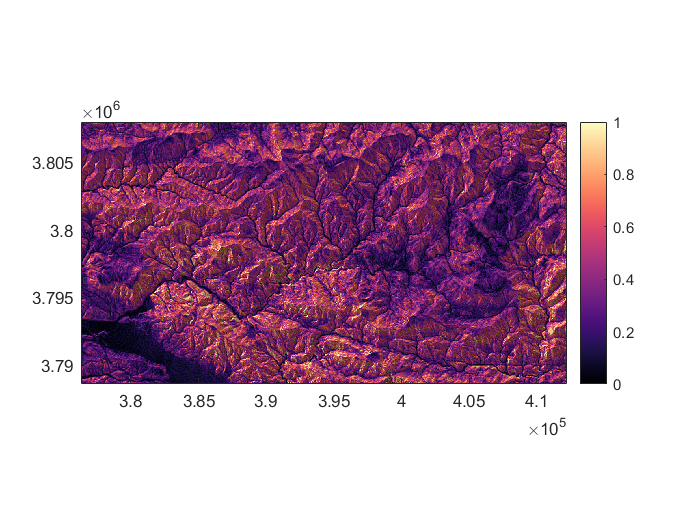

DEM = GRIDobj('srtm_bigtujunga30m_utm11.tif');
G   = gradient8(DEM);
imageschs(DEM,G,'caxis',[0 1],'colormap','magmacolor')

The function `arcslope` uses the same approach as used by ESRI ArcGIS. 

G2  = arcslope(DEM);
imageschs(DEM,G,'caxis',[0 1],'colormap','magmacolor')

## Aspect

Aspect determines the exposition of a slope. 

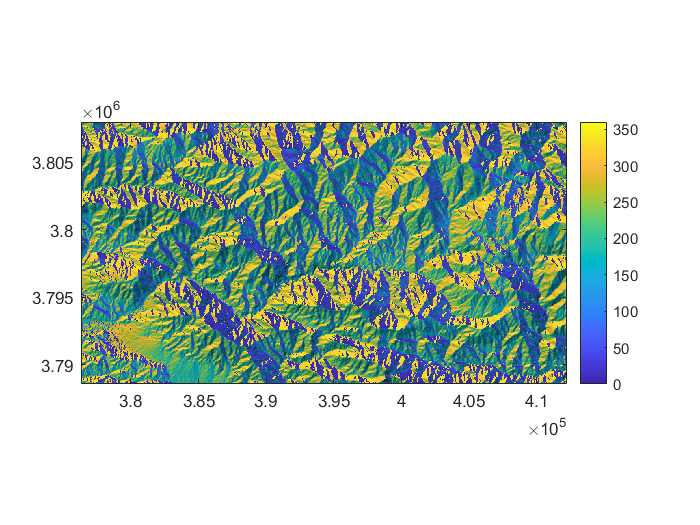

ASP = aspect(DEM);
imageschs(DEM,ASP,'caxis',[0 360])

## Curvature

Curvature is the second derivative and measures the rate of change of slope. Profile curvature is the rate of slope change in direction of the maximum gradient. Conversely, planform curvature measures the curvature of the contour lines. The function` curvature` allows calculating both types of curvature in addition to some additionally, less frequently used forms of curvature. Curvature is very sensitive to errors in the DEM. Thus, when plotting, we only plot the data between the 2nd and 98th percentile of the data.

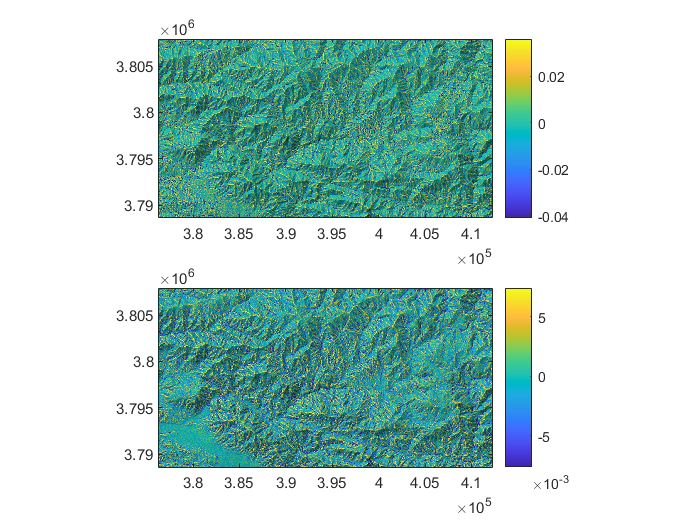

Cplan = curvature(DEM,'planc');
Cprof = curvature(DEM,'profc');
subplot(2,1,1)
title('Planform curvature')
imageschs(DEM,Cplan,'percentclip',2)
subplot(2,1,2)
title('Profile curvature')
imageschs(DEM,Cprof,'percentclip',2)